## Generating Independent Draws from $$P_{Y_{N}}$$

rng(0);
m = 10000;
x = 1;
hold on;
while x <= 64
    q = aver(x,m);
    t=sort(q);
    a = unique(t);
    freq = zeros(1,length(a));
    for i=1:1:length(a)
        freq(1,i) = sum(t(1,:)==a(1,i));
    end

Averaged value are calculated by $\texttt{aver(.)}$ (defined below). Then we make array of all  unique entries of x and their frequencies are also calculated; CDF is plotted by using cumsum function on these frequencies.

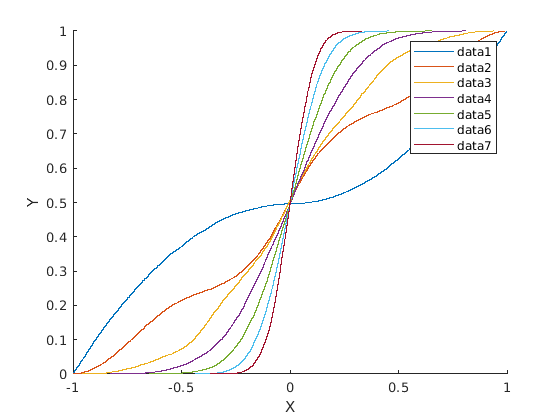

    freq_cdf = cumsum(freq)./m;
    plot(a,freq_cdf);
    x =x.*2;
end
hold off;

legend("show")
xlabel("X")
ylabel("Y")

Definition of $\texttt{aver(.)}$ below,

function avg = aver(n,m)
    avg = rand(n,m);
    for i=1:1:m
        for j = 1:1:n
            if avg(j,i) > 0.5
                avg(j,i) = sqrt(2*avg(j,i) - 1);
            else
                avg(j,i) = -1*(sqrt(1-2*avg(j,i)));
            end
        end
    end
    avg = sum(avg,1);
    avg = avg./n;    
end